# Get Whisker Contacts from Trace

From function getContactTimes. Reads ntrode trace of contact signal and calculates times and indices of contact onsets. Requires various manually selected thresholds. Livescript version might help with plotting.

Adapted from Amanda's getContactTimes_wholetrace_timesOnly.m

Read in ntrode file

fpath = 'D:\Data\GP09-7\160608-001\';
nfile = '160608-01';
samplingRate = 16000;
dt = 1000/samplingRate;
stimDur = 1500;

contacts = readNtrode(fpath,nfile,{'top_contact','bot_contact','trial_start'});
rawContactTop = contacts.top_contact;
rawContactBottom = contacts.bot_contact;
totalTime = length(rawContactTop)*dt;
trialStartSig = contacts.trial_start;
trialStartTimes = getEventTimes(trialStartSig, samplingRate,'negative');

Plot whole trace for top and bottom contacts

figure
hold on
plot(dt:dt:length(rawContactTop)*dt,rawContactTop,'r')
axis tight
title('top contact signal')
xlabel('time (ms)')

figure
hold on
plot(dt:dt:length(rawContactBottom)*dt,rawContactBottom,'r')
axis tight
title('bottom contact signal')
xlabel('time (ms)')

Select a range of trials to plot a smaller amount of data

firstTrialTop = 120;
stopTrialTop = 150;
firstTrialBottom = 120;
stopTrialBottom =  150;

Plot the data between those trials

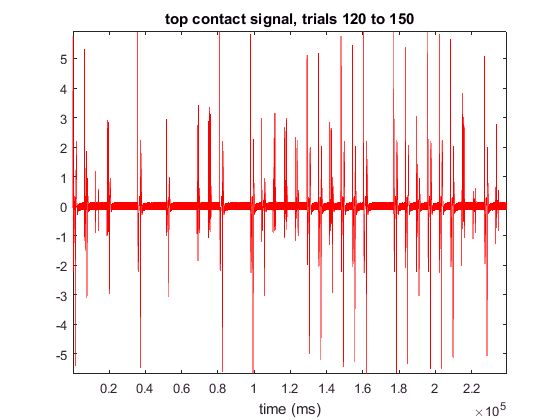

startPlotTop = trialStartTimes(firstTrialTop);
startPlotTop = startPlotTop/dt;
endPlotTop = trialStartTimes(stopTrialTop);
endPlotTop = endPlotTop/dt;

startPlotBottom = trialStartTimes(firstTrialBottom);
startPlotBottom = startPlotBottom/dt;
endPlotBottom = trialStartTimes(stopTrialBottom);
endPlotBottom = endPlotBottom/dt;

figure
plot(dt:dt:length(rawContactTop(startPlotTop:endPlotTop))*dt,rawContactTop(startPlotTop:endPlotTop),'r')
hold on
axis tight
title(['top contact signal, trials ' num2str(firstTrialTop) ' to ' num2str(stopTrialTop)])
xlabel('time (ms)')

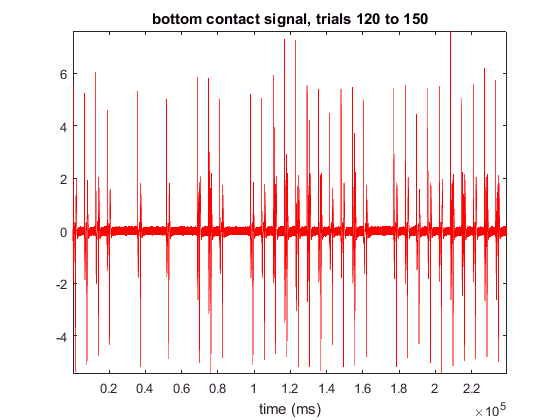


figure
plot(dt:dt:length(rawContactBottom(startPlotBottom:endPlotBottom))*dt,rawContactBottom(startPlotBottom:endPlotBottom),'r')
hold on
axis tight
title(['bottom contact signal, trials ' num2str(firstTrialBottom) ' to ' num2str(stopTrialBottom)])
xlabel('time (ms)')

Band-pass filtering data to get rid of high-frequency electrical noise and low frequency baseline shifts

cutoffFreq = [20 3000];
cfreq = cutoffFreq/samplingRate;
[b,a] = butter(1,[cfreq],'bandpass');
filtContactTop = filtfilt(b,a,rawContactTop);
filtContactBottom = filtfilt(b,a,rawContactBottom);

Plot filtered contact trace over raw contact trace

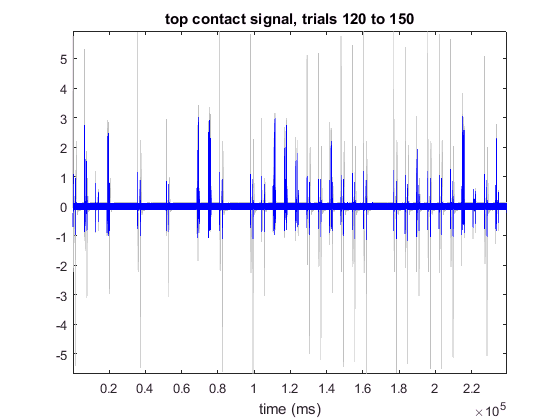

figure
plot(dt:dt:length(rawContactTop(startPlotTop:endPlotTop))*dt,rawContactTop(startPlotTop:endPlotTop),'Color',[192/255,192/255,192/255])
hold on
plot(dt:dt:length(filtContactTop(startPlotTop:endPlotTop))*dt,filtContactTop(startPlotTop:endPlotTop),'b')
axis tight
title(['top contact signal, trials ' num2str(firstTrialBottom) ' to ' num2str(stopTrialBottom)])
xlabel('time (ms)')

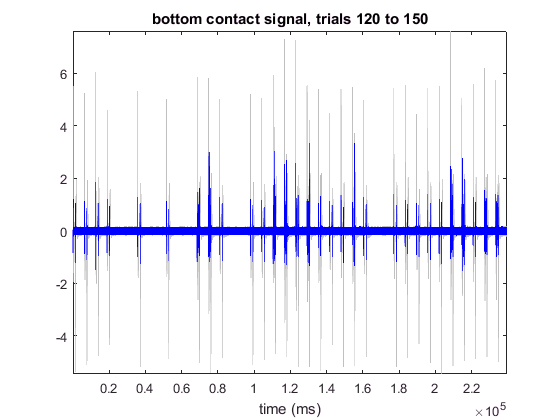


figure
plot(dt:dt:length(rawContactBottom(startPlotBottom:endPlotBottom))*dt,rawContactBottom(startPlotBottom:endPlotBottom),'Color',[192/255,192/255,192/255])
hold on
plot(dt:dt:length(filtContactBottom(startPlotBottom:endPlotBottom))*dt,filtContactBottom(startPlotBottom:endPlotBottom),'b')
axis tight
title(['bottom contact signal, trials ' num2str(firstTrialBottom) ' to ' num2str(stopTrialBottom)])
xlabel('time (ms)')

Cut out motor artefact

motorCutTop = [170, 120];
preMotorTop = 100;
motorCutBottom = [170, 120];
preMotorBottom = 100;
contactTop = cutoutNoise(filtContactTop,trialStartTimes,dt,motorCutTop(1)); %cut out around motor moving into position (at trial start times)
contactTop = cutoutNoise(contactTop,trialStartTimes+stimDur-preMotorTop,dt,motorCutTop(2)); %cut out around motor moving out of position (at end of stim dur)
contactBottom = cutoutNoise(filtContactBottom,trialStartTimes,dt,motorCutBottom(1));
contactBottom = cutoutNoise(contactBottom,trialStartTimes+stimDur-preMotorBottom,dt,motorCutBottom(2));

Plot cut contact (green) signal over filtered contact signal (blue) over raw contact signal (gray)

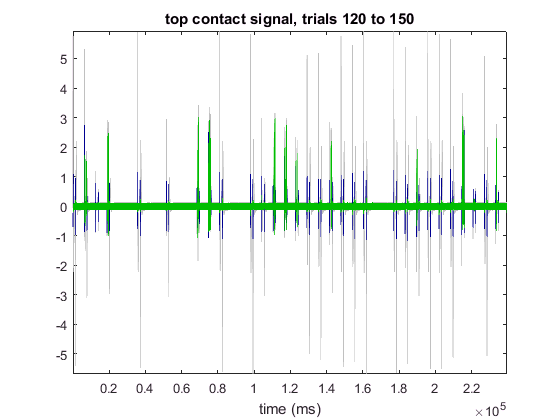

figure
plot(dt:dt:length(rawContactTop(startPlotTop:endPlotTop))*dt,rawContactTop(startPlotTop:endPlotTop),'Color',[192/255,192/255,192/255])
hold on
plot(dt:dt:length(filtContactTop(startPlotTop:endPlotTop))*dt,filtContactTop(startPlotTop:endPlotTop),'Color',[0,0,145/255])
plot(dt:dt:length(contactTop(startPlotTop:endPlotTop))*dt,contactTop(startPlotTop:endPlotTop),'Color',[0,190/255,0])
axis tight
title(['top contact signal, trials ' num2str(firstTrialBottom) ' to ' num2str(stopTrialBottom)])
xlabel('time (ms)')

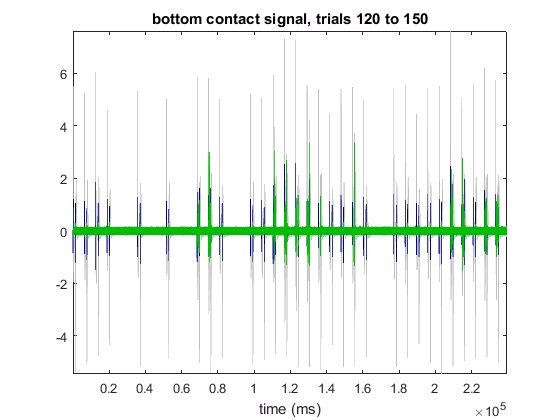


figure
plot(dt:dt:length(rawContactBottom(startPlotBottom:endPlotBottom))*dt,rawContactBottom(startPlotBottom:endPlotBottom),'Color',[192/255,192/255,192/255])
hold on
plot(dt:dt:length(filtContactBottom(startPlotBottom:endPlotBottom))*dt,filtContactBottom(startPlotBottom:endPlotBottom),'Color',[0,0,145/255])
plot(dt:dt:length(contactBottom(startPlotBottom:endPlotBottom))*dt,contactBottom(startPlotBottom:endPlotBottom),'Color',[0,190/255,0])
axis tight
title(['bottom contact signal, trials ' num2str(firstTrialBottom) ' to ' num2str(stopTrialBottom)])
xlabel('time (ms)')

Select a threshold for contacts and plot it over the figure

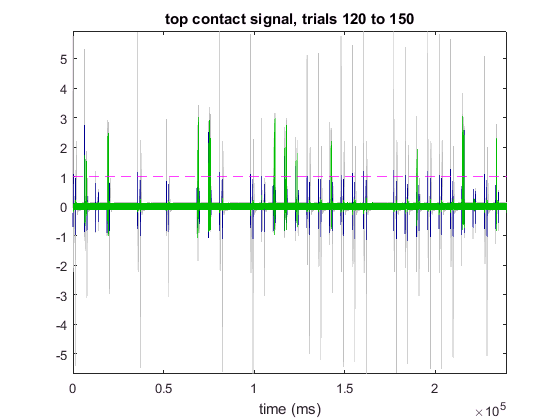

threshTop = 1;
threshBottom = .5;

figure
plot(dt:dt:length(rawContactTop(startPlotTop:endPlotTop))*dt,rawContactTop(startPlotTop:endPlotTop),'Color',[192/255,192/255,192/255])
hold on
plot(dt:dt:length(filtContactTop(startPlotTop:endPlotTop))*dt,filtContactTop(startPlotTop:endPlotTop),'Color',[0,0,145/255])
plot(dt:dt:length(contactTop(startPlotTop:endPlotTop))*dt,contactTop(startPlotTop:endPlotTop),'Color',[0,190/255,0])
axis tight
title(['top contact signal, trials ' num2str(firstTrialBottom) ' to ' num2str(stopTrialBottom)])
xlabel('time (ms)')
line([0 length(contactTop(startPlotTop:endPlotTop))*dt],[threshTop threshTop],'LineStyle','--','Color','m')

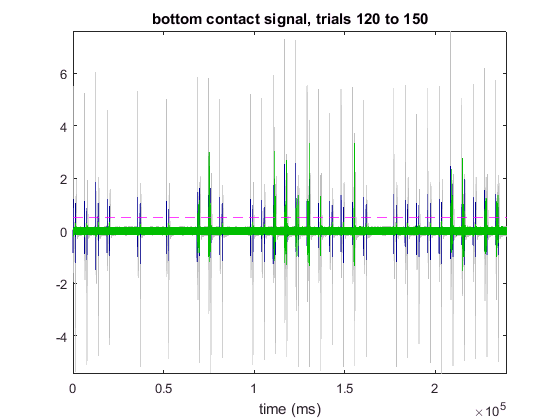


figure
plot(dt:dt:length(rawContactBottom(startPlotBottom:endPlotBottom))*dt,rawContactBottom(startPlotBottom:endPlotBottom),'Color',[192/255,192/255,192/255])
hold on
plot(dt:dt:length(filtContactBottom(startPlotBottom:endPlotBottom))*dt,filtContactBottom(startPlotBottom:endPlotBottom),'Color',[0,0,145/255])
plot(dt:dt:length(contactBottom(startPlotBottom:endPlotBottom))*dt,contactBottom(startPlotBottom:endPlotBottom),'Color',[0,190/255,0])
axis tight
title(['bottom contact signal, trials ' num2str(firstTrialBottom) ' to ' num2str(stopTrialBottom)])
xlabel('time (ms)')
line([0 length(contactBottom(startPlotBottom:endPlotBottom))*dt],[threshBottom threshBottom],'LineStyle','--','Color','m')

Find indices of potential contacts (things with a certain refractive period that cross the threshold)

refract = 0; %in ms

contactTopInd = calcContactTimes_c(contactTop,threshTop,refract,dt);
contactTopTimes = round(contactTopInd*dt);
disp(['Found ',num2str(length(contactTopTimes)),' top contacts'])

Found 889 top contacts



contactBottomInd = calcContactTimes_c(contactBottom,threshBottom,refract,dt);
contactBottomTimes = round(contactBottomInd*dt);
disp(['Found ',num2str(length(contactBottomTimes)),' bottom contacts'])

Found 2517 bottom contacts


Find the baseline of the filtered signal

%Find mean of filtered ITI
ITIstarts = trialStartTimes(1:end-1)+stimDur+50;
ITIends = trialStartTimes(2:end)-10;
baselineTop = mean(contactTop(ITIstarts:ITIends));
baselineBottom = mean(contactBottom(ITIstarts:ITIends));
% %plot the baseline
% figure(j)
% line([0 length(contactTop(startPlotTop:endPlotTop))*dt],[baselineTop baselineTop],'LineStyle','--','Color','k')
% 
% figure(h)
% line([0 length(contactBottom(startPlotBottom:endPlotBottom))*dt],[baselineBottom baselineBottom],'LineStyle','--','Color','k')

For TOP contacts: Sort out which putative contact indices are real contact start times by demanding that the signal return to baseline between the current contact peak and the next contact peak. Otherwise we are still looking at the same contact.

extraTop  = 0;
%need to add something that determines if new trial between contacts.
%otherwise if it doesn't cross the threshold, the first contact on next trial
%will be skipped
tempContacts = contactTopInd;
c=1;
while c < length(tempContacts)
    tempSig = contactTop(tempContacts(c):tempContacts(c+1));
    crossing = tempSig<=(baselineTop-extraTop); %does the signal between contacts cross the threshold? May need to lower baseline threshold
    if sum(crossing)<1 %if not, delete this point for deletion
        tempContacts(c+1)=[];
    else
        c=c+1;
    end
    if length(tempContacts)==1 %deleted all the contacts except the first, which you never check
        break
    end
end

possContactTopInd = tempContacts;

Now plot these onto our contact signal plot

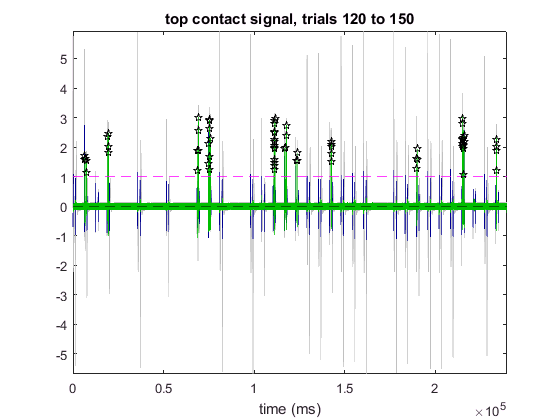

figure
plot(dt:dt:length(rawContactTop(startPlotTop:endPlotTop))*dt,rawContactTop(startPlotTop:endPlotTop),'Color',[192/255,192/255,192/255])
hold on
plot(dt:dt:length(filtContactTop(startPlotTop:endPlotTop))*dt,filtContactTop(startPlotTop:endPlotTop),'Color',[0,0,145/255])
plot(dt:dt:length(contactTop(startPlotTop:endPlotTop))*dt,contactTop(startPlotTop:endPlotTop),'Color',[0,190/255,0])
axis tight
title(['top contact signal, trials ' num2str(firstTrialTop) ' to ' num2str(stopTrialTop)])
xlabel('time (ms)')
line([0 length(contactTop(startPlotTop:endPlotTop))*dt],[threshTop threshTop],'LineStyle','--','Color','m')
line([0 length(contactTop(startPlotTop:endPlotTop))*dt],[baselineTop baselineTop],'LineStyle','--','Color','k')

contactsPlotTop = possContactTopInd(possContactTopInd > startPlotTop & possContactTopInd < endPlotTop);
contactsPlotTop = contactsPlotTop - startPlotTop;
plot(contactsPlotTop*dt,contactTop(startPlotTop+contactsPlotTop),'kp')

For BOTTOM contacts: Sort out which putative contact indices are real contact start times by demanding that the signal return to baseline between the current contact peak and the next contact peak.

extraBottom = 0.3;

tempContacts = contactBottomInd;
c=1;
while c < length(tempContacts)
    tempSig = contactBottom(tempContacts(c):tempContacts(c+1));
    crossing = tempSig<=(baselineBottom-extraBottom); %does the signal between contacts cross the threshold?
    if sum(crossing)<1 %if not, delete this point for deletion
        tempContacts(c+1)=[];
    else
        c=c+1;
    end
    if length(tempContacts)==1 %deleted all the contacts except the first, which you never check
        break
    end
end

possContactBottomInd = tempContacts;

Now plot these putative bottom contacts

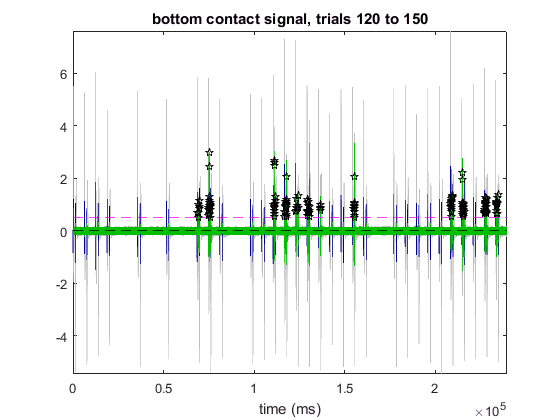

figure
plot(dt:dt:length(rawContactBottom(startPlotBottom:endPlotBottom))*dt,rawContactBottom(startPlotBottom:endPlotBottom),'Color',[192/255,192/255,192/255])
hold on
plot(dt:dt:length(filtContactBottom(startPlotBottom:endPlotBottom))*dt,filtContactBottom(startPlotBottom:endPlotBottom),'Color',[0,0,145/255])
plot(dt:dt:length(contactBottom(startPlotBottom:endPlotBottom))*dt,contactBottom(startPlotBottom:endPlotBottom),'Color',[0,190/255,0])
axis tight
title(['bottom contact signal, trials ' num2str(firstTrialBottom) ' to ' num2str(stopTrialBottom)])
xlabel('time (ms)')
line([0 length(contactBottom(startPlotBottom:endPlotBottom))*dt],[threshBottom threshBottom],'LineStyle','--','Color','m')
line([0 length(contactBottom(startPlotBottom:endPlotBottom))*dt],[baselineBottom baselineBottom],'LineStyle','--','Color','k')

contactsPlotBottom = possContactBottomInd(possContactBottomInd > startPlotBottom & possContactBottomInd < endPlotBottom);
contactsPlotBottom = contactsPlotBottom - startPlotBottom;
plot(contactsPlotBottom*dt,contactBottom(startPlotBottom+contactsPlotBottom),'kp')

Consider adding a section that looks at different trials and plots those contacts again

Save everything? DOES THIS STILL WORK CONSISTENTLY?

cd(fpath)
contactTopInd = possContactTopInd;
contactBottomInd = possContactBottomInd;

contactTopTimes = round(contactTopInd*dt);
contactBottomTimes = round(contactBottomInd*dt);
disp(['Found ',num2str(length(contactTopTimes)),' top contacts'])

Found 457 top contacts


disp(['Found ',num2str(length(contactBottomTimes)),' bottom contacts'])

Found 1355 bottom contacts



%Save contacts times, saved as a list of times
disp('Saving .mat file...')

Saving .mat file...


if exist([nfile '-contactData.mat'],'file')
    save([nfile '-contactData.mat'],'contactBottomTimes','contactTopTimes','contactTopInd','-append')
else
    save([nfile '-contactData.mat'],'contactBottomTimes','contactTopTimes','contactBottomInd','contactTopInd')
end